clear all;
clc;

%parametros do filtro
sigma = 2;
Janela = 2 * ceil(3 * sigma) + 1;


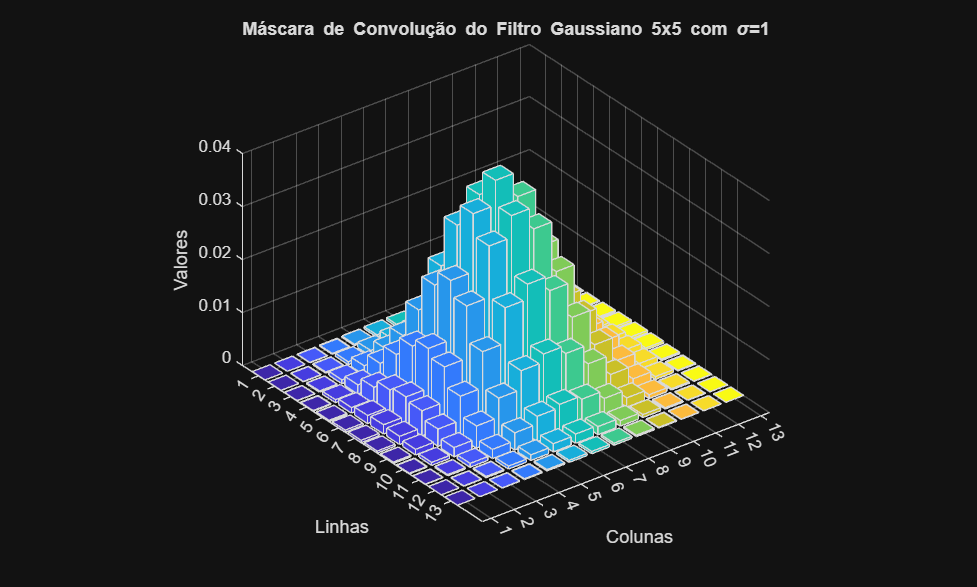

%Criação das matrizes coluna e linha com a gaussiana
Gaussiana_linha = zeros(Janela);
for x = 1:Janela
        Gaussiana_linha(x) = exp(-((x-ceil(Janela/2))^2) / (2 * sigma^2));
end
Gaussiana_linha = Gaussiana_linha/sum(Gaussiana_linha);
Gaussiana_coluna = Gaussiana_linha';
Masc_Gaussiana = Gaussiana_linha*Gaussiana_coluna;

figure;%Verificar se a mascara ficou correta
bar3(Masc_Gaussiana);
title('Máscara de Convolução do Filtro Gaussiano 5x5 com \sigma=1');
xlabel('Colunas');
ylabel('Linhas');
zlabel('Valores');

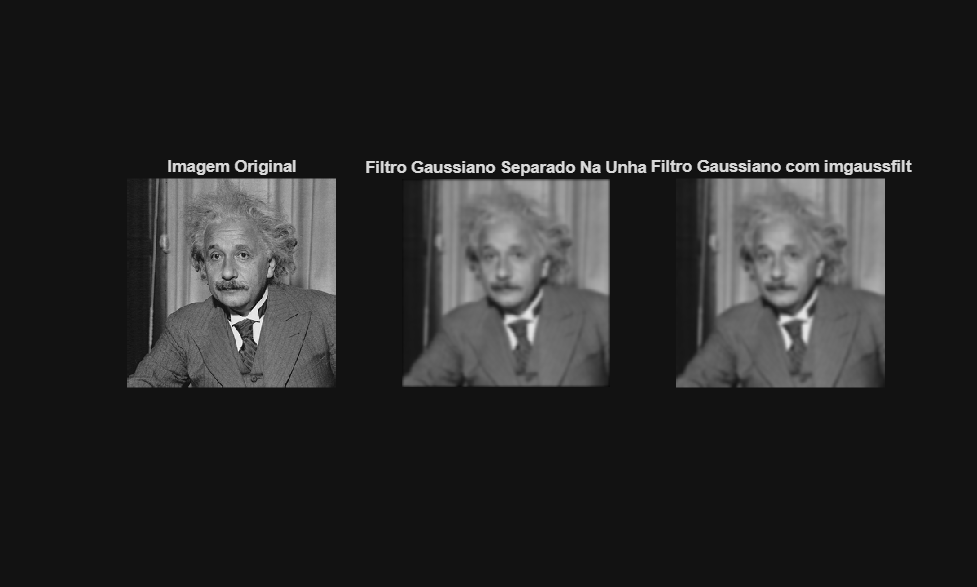

img = imread("einstein.gif");

% Aplicar a convolução na imagem com o filtro gaussiano (separado em linha e coluna)
img_unha = conv2(img,Gaussiana_linha,"same");
img_unha = conv2(img_unha,Gaussiana_coluna,"same");

% Aplicar o filtro gaussiano diretamente com imgaussfilt para comparação
img_matlab = imgaussfilt(img, sigma);

figure;

subplot(1, 3, 1);
imshow(uint8(img));
title('Imagem Original');

subplot(1, 3, 2);
imshow(uint8(img_unha));
title('Filtro Gaussiano Separado Na Unha');

subplot(1, 3, 3);
imshow(uint8(img_matlab));
title('Filtro Gaussiano com imgaussfilt');